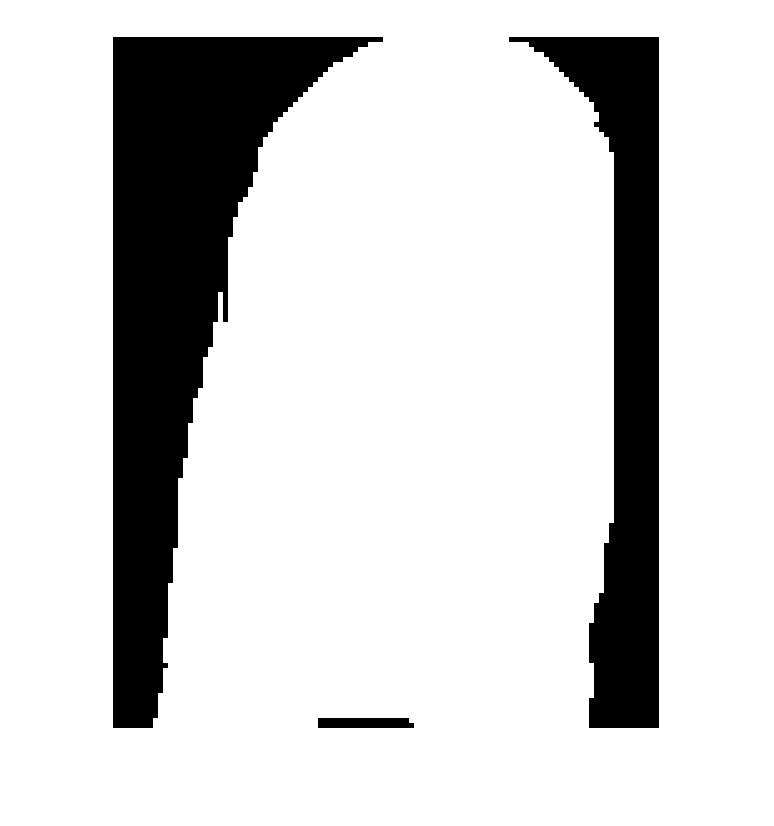

img = imread('img/img1.jpg');
mask = segmentation(im2double(img), 10);
imshow(mask);

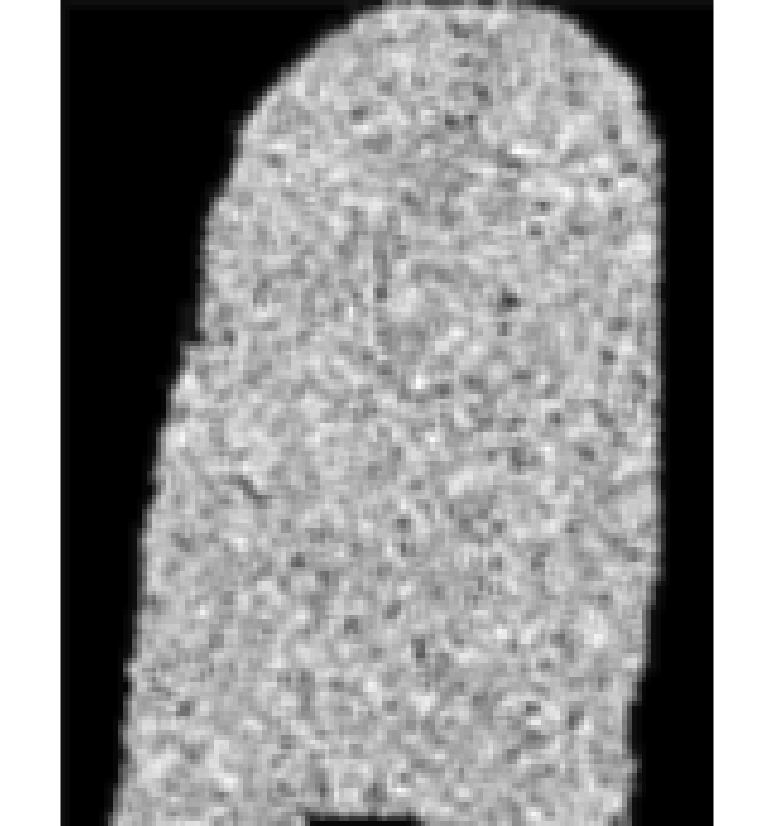

img = rgb2gray(img);
img_fg = im2double(img) .* mask;                                          
img_fg = im2uint8(img_fg);                                %要转化不然报错
part_piece = 8;           
extend = 16 ;
[ angle_array , wavelength ,frequency ] = Get_angle_array (img_fg, part_piece, extend);
[angle_array, wavelength] = smooth_dir_frq(angle_array, wavelength, frequency, part_piece);

img_enhanced = enhancement(angle_array, frequency, mask, img_fg, part_piece, extend);

错误使用 imwrite (line 541)
无法打开要写入的文件 "output\_output_filter.jpg"。您可能没有写入权限。

出错 enhancement (line 19)
    imwrite(enhancement_pic,['output\','_output_filter.jpg']);

imshow(img_enhanced);